
%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=2059s,22330s,22113s,23916s


ind2 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     11    12    11    10     9     9    10    10     9     9     9     9     8     8     9     9     8     8     9     9
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     2
    22    22    22    22    22    22    22    22    22    22    22    22    23    23    23    23    23    23    23    23
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind2)

ans =     47    51    50    50    49    49    49    49    48    48    49    49    49    49    48    48    47    46    46    47


mean(sum(ind2))

ans = 48.4000

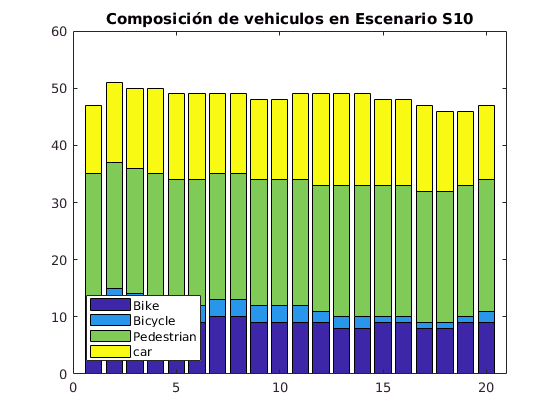


figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])